ImageFile = '1_ales-krivec-3727.png';
sizeWork = [768 1280];

sizeWork =          768        1280



I = (SmartResize(imread(ImageFile), sizeWork));

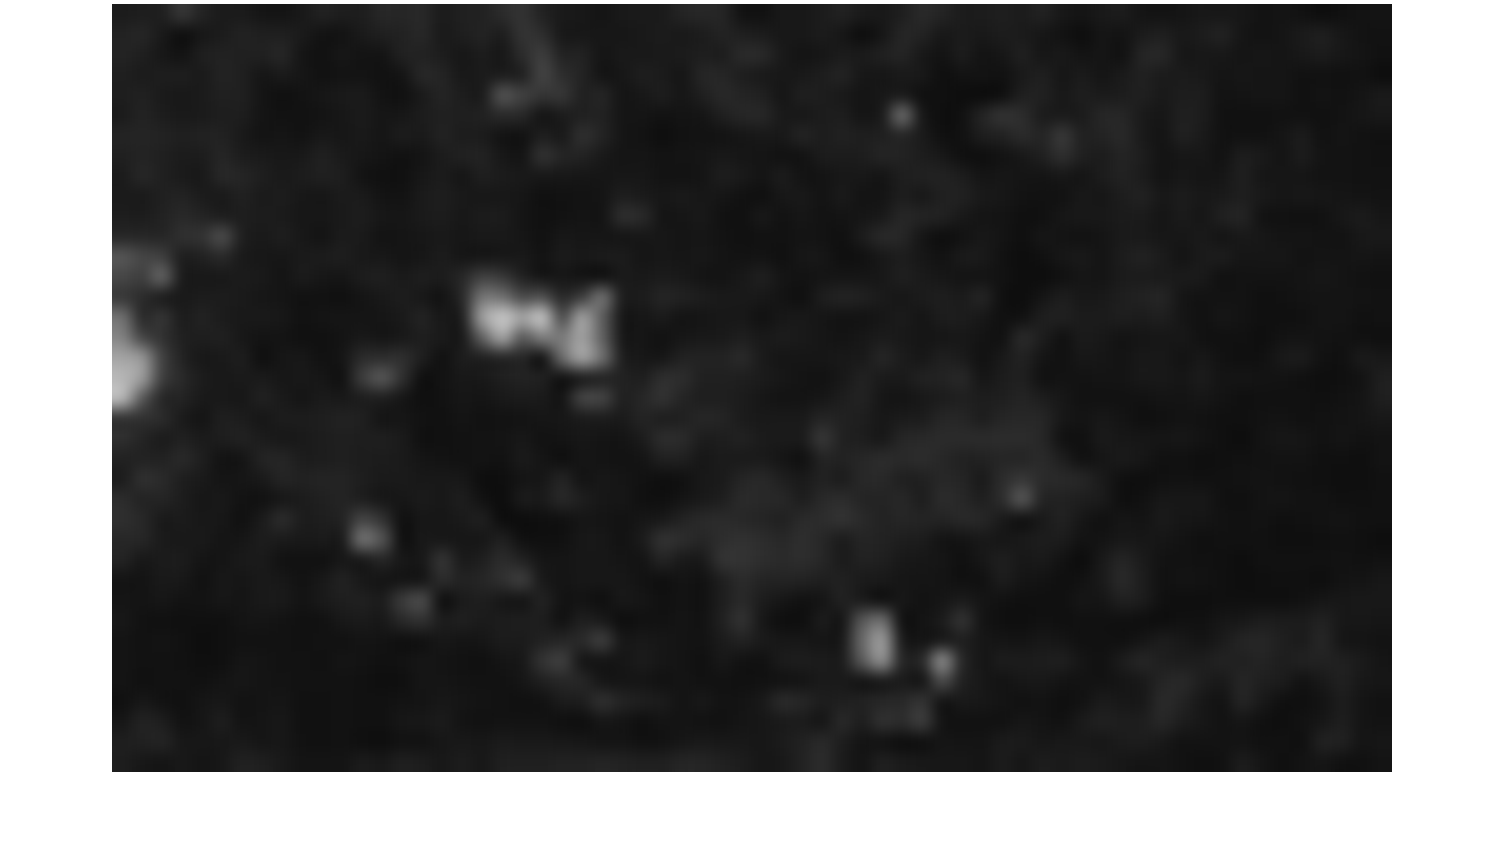

imshow(I)

ImageData = cell(0);

for i = 1:64:sizeWork(1,1)
    for j = 1:64:sizeWork(1,2)
        
        ImageData{end+1} = I(i:i+63, j:j+63);
        
    end
end



SCALES = [1 2 4 8];

for s = 1: length(SCALES)
    
    S = SCALES(s);
    
    for Q = 0:100
        
        for i= 1:size(ImageData,2)
            
            imwrite(imresize(ImageData{i},[64 64]./s), 'temp.jpeg', 'Quality',Q)
            SSIM(s,Q+1,i) = ssim(imresize(imread('temp.jpeg'), [64 64]), ImageData{i});
            PSNR(s,Q+1,i) = psnr(imresize(imread('temp.jpeg'), [64 64]), ImageData{i});
            
            f = fopen('temp.jpeg');
            temp = string(dec2hex(fread(f)));
            fclose(f);
            
            Data = strcat(temp{:});
            FrameStartIndx = strfind(Data, 'FFDA')+4;
            FrameData = Data(FrameStartIndx:end-2);
            CompressedBytes(s,Q+1,i) = length(FrameData)/2;
            
        end
            
        
    end
    
end


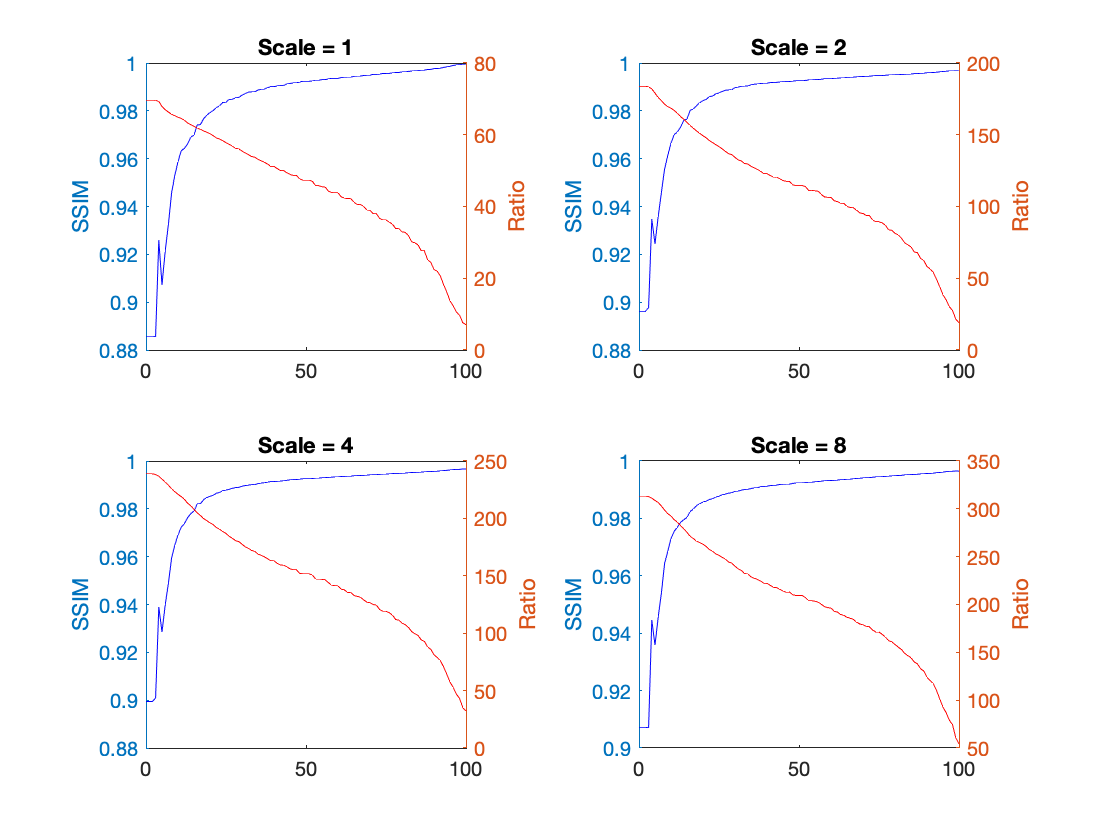

  figure
for i =1:4
  
    subplot(2,2,i)
    
    yyaxis right
    plot(0:100,(64*64)./(mean(CompressedBytes(i,:,:),3)), 'r');
    ylabel('Ratio');
%     plot(mean(PSNR(i,:,:),3), 'g')

    yyaxis left
    plot(0:100, mean(SSIM(i,:,:),3), 'b')
    ylabel('SSIM')
    
    title(['Scale = ' num2str(SCALES(i)) ])
end

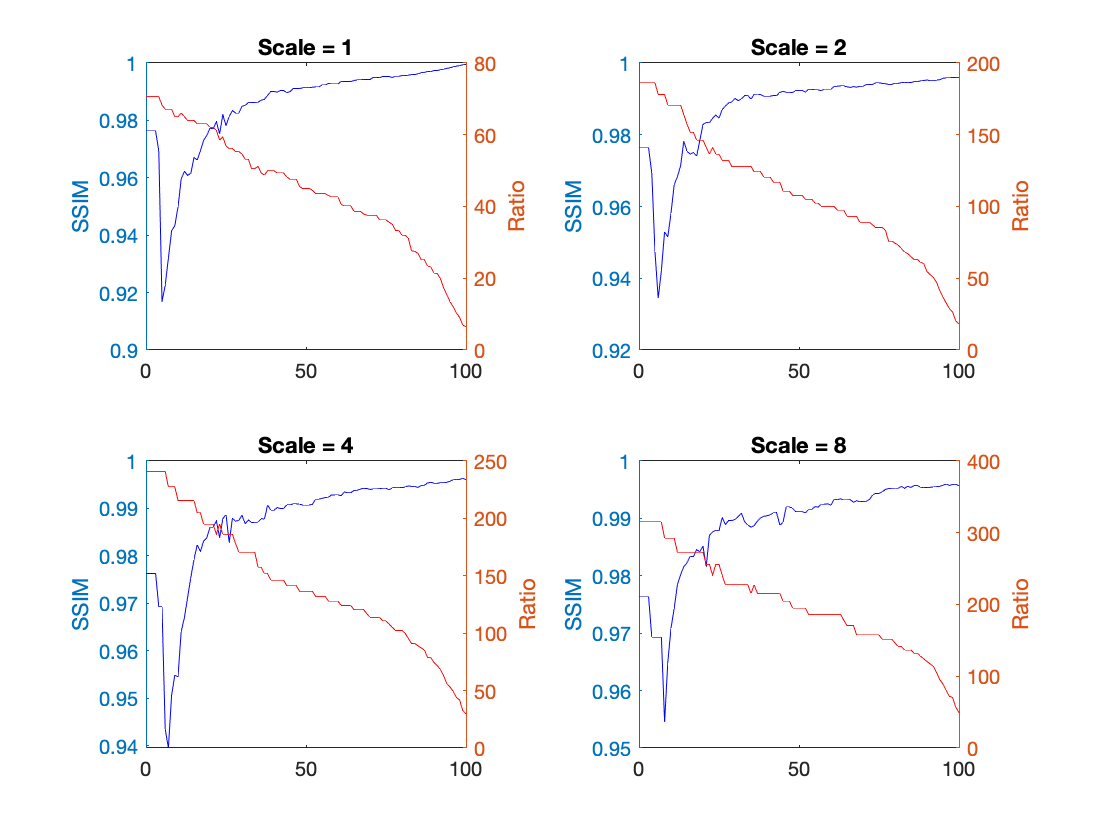

  figure
  N = 10;
for i =1:4
  
    subplot(2,2,i)
    
    yyaxis right
    plot(0:100,(64*64)./(mean(CompressedBytes(i,:,N),3)), 'r');
    ylabel('Ratio');
%     plot(mean(PSNR(i,:,:),3), 'g')

    yyaxis left
    plot(0:100, mean(SSIM(i,:,N),3), 'b')
    ylabel('SSIM')
    
    title(['Scale = ' num2str(SCALES(i)) ])
end